ttf median


R_squared = 0.9839

ttf worst


R_squared = 0.9551

early ttf median


R_squared = 0.8316

early ttf worst


R_squared = 0.4145

b-filter median


R_squared = 0.9277

b-filter worst


R_squared = 0.5875

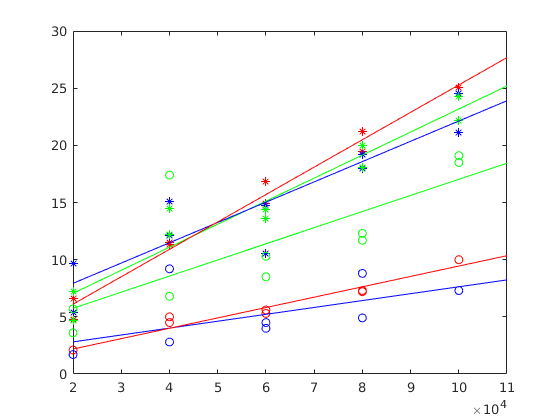

ttf median


R_squared = 0.6060

ttf worst


R_squared = 0.4423

early ttf median


R_squared = 0.4638

early ttf worst


R_squared = 0.2884

b-filter median


R_squared = 0.6659

b-filter worst


R_squared = 0.2465

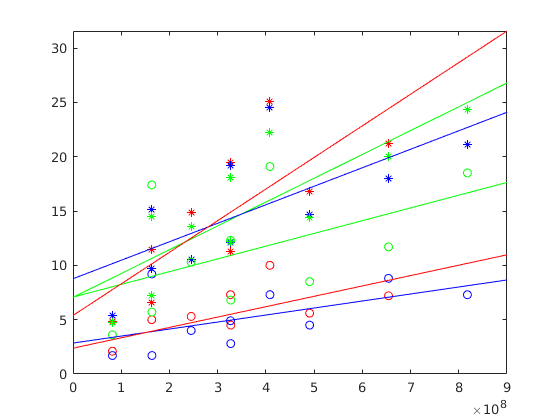

ttf median


R_squared = 0.9690

ttf worst


R_squared = 0.8673

early ttf median


R_squared = 0.7946

early ttf worst


R_squared = 0.3714

b-filter median


R_squared = 0.9157

b-filter worst


R_squared = 0.4837

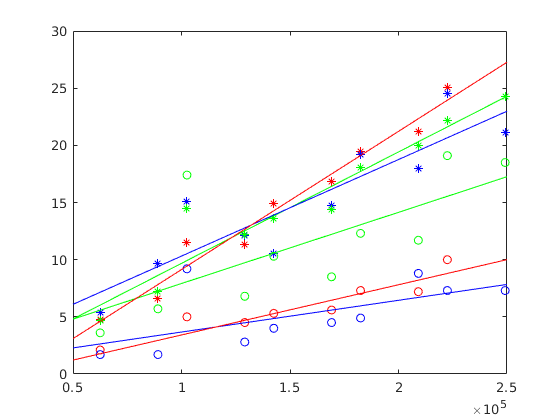

filename1 = '/home/jeremydohmann/Documents/hdd/home/Documents/Thesis/appendix/code/btreefiltering/sparse_tree/terminal_tree_filter_stats.csv';
filename2 = '/home/jeremydohmann/Documents/hdd/home/Documents/Thesis/appendix/code/btreefiltering/sparse_tree/terminating_tree_stats.csv';
filename3 = '/home/jeremydohmann/Documents/hdd/home/Documents/Thesis/appendix/code/btreefiltering/sparse_tree/basic_filter_stats.csv';
run_results(filename1, filename2, filename3)

function run_results(file1, file2, file3)
    M = csvread(file1, 1, 0);
    g1 = M(:,1);
    t1 = M(:,2);
    p1 = M(:,3);
    worst1 = M(:,4);
    worst_len1 = M(:,5);
    median1 = M(:,6);
    median_len1 = M(:,7);
    
    M = csvread(file2, 1, 0);
    g2 = M(:,1);
    t2 = M(:,2);
    p2 = M(:,3);
    worst2 = M(:,4);
    worst_len2 = M(:,5);
    median2 = M(:,6);
    median_len2 = M(:,7);
    
    M = csvread(file3, 1, 0);
    g3 = M(:,1);
    t3 = M(:,2);
    p3 = M(:,3);
    worst3 = M(:,4);
    worst_len3 = M(:,5);
    median3 = M(:,6);
    median_len3 = M(:,7);
    plot_results(t1,t2, t3, worst1, median1, worst2, median2, worst3, median3)
    plot_results(p1.*t1,p2.*t2, p3.*t3, worst1, median1, worst2, median2, worst3, median3)
    plot_results(g1,g2, g3, worst1, median1, worst2, median2, worst3, median3)
end

function plot_results(x1, x2, x3, y1, y2, y3, y4, y5, y6)
    rng default;  % For reproducibility
    figure;

    plot(x1,y1,'r*')
    hold on

    plot(x1,y2,'ro')
    
    plot(x2,y3,'b*')
    hold on

    plot(x2,y4,'bo')
    
    plot(x3,y5,'g*')
    hold on

    plot(x3,y6,'go')
    
    disp("ttf median")
    R=corrcoef(x1,y1);
    R_squared=R(2)^2
    
    disp("ttf worst")
    R=corrcoef(x1,y2);    
    R_squared=R(2)^2
    
    disp("early ttf median")
    R=corrcoef(x2,y3);
    R_squared=R(2)^2
    
    disp("early ttf worst")
    R=corrcoef(x2,y4);
    R_squared=R(2)^2
    
    disp("b-filter median")
    R=corrcoef(x3,y5);
    R_squared=R(2)^2
    
    disp("b-filter worst")
    R=corrcoef(x3,y6);
    R_squared=R(2)^2
    lsline
end